# (a) 2D steady state diffusion equation:(Successive over relaxation method, $\omega$=1.5) 

# 
$$\frac{\delta^2{u}}{\delta{x^2}}{(x,y)}+\frac{\delta^2{u}}{\delta{y^2}}{(x,y)}=0$$


Central difference formula is used in space.


clearvars

% Parameters
Lx = 1.0;         % Length of the domain in x
Ly = 1.0;         % Length of the domain in y
Nx = 51;          % Number of grid points in x
Ny = 51;          % Number of grid points in y
dx = Lx / (Nx - 1); % Grid spacing in x
dy = Ly / (Ny - 1); % Grid spacing in y
x = linspace(0, Lx, Nx);
y = linspace(0, Ly, Ny);
[X, Y] = meshgrid(x, y);

% Boundary conditions
u = zeros(Nx, Ny);
u(:, 1) = 0;        % u(x,0) = 0
u(:, Ny) = 1;       % u(x,1) = 1
u(1, :) = 0;        % u(0,y) = 0
u(Nx, :) = 0;       % u(1,y) = 0

% Time-stepping loop (steady state) using SOR method
max_iterations = 5000;
tolerance = 1e-6;
omega = 1.5; % Over-relaxation parameter

for iter = 1:max_iterations
    max_change = 0;
    for i = 2:Nx-1
        for j = 2:Ny-1
            u_old = u(i, j);
            u(i, j) = (1 - omega) * u(i, j) + (omega / 4) * (u(i+1, j) + u(i-1, j) + u(i, j+1) + u(i, j-1));
            max_change = max(max_change, abs(u_old - u(i, j)));
        end
    end
    
    % Check for convergence
    if max_change < tolerance
        disp(['Convergence reached at iteration ' num2str(iter)]);
        break;
    end
end

Convergence reached at iteration 725


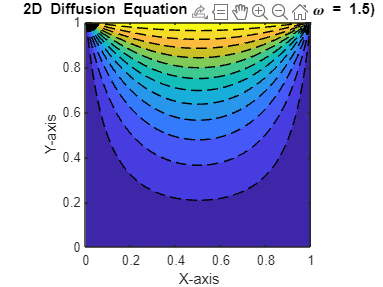


% Visualizing the solution using contour plot
contourf(X, Y, u', 12, '--');
xlabel('X-axis');
ylabel('Y-axis');
title('2D Diffusion Equation Solution (SOR, \omega = 1.5)');
axis equal;